# Визуализация в MATLAB

Визуализируем демографические данные

## Загрузка данных

Загрузим данные из файла `agestat.mat`

load agestat

Переменная `M` содержит возраст мужчин, а переменная `F` - возраст женщин в загруженной выборке.

Найдем количество мужчин и женщин в выборке

n = [length(M) length(F)];

## Визуализация данных

Отобразим соотношение мужчин и женщин и настроим график

### 1. Ручная настройка в Live Editor

Построим столбчатую диаграмму, отражающую количество мужчин и женщин в выборке

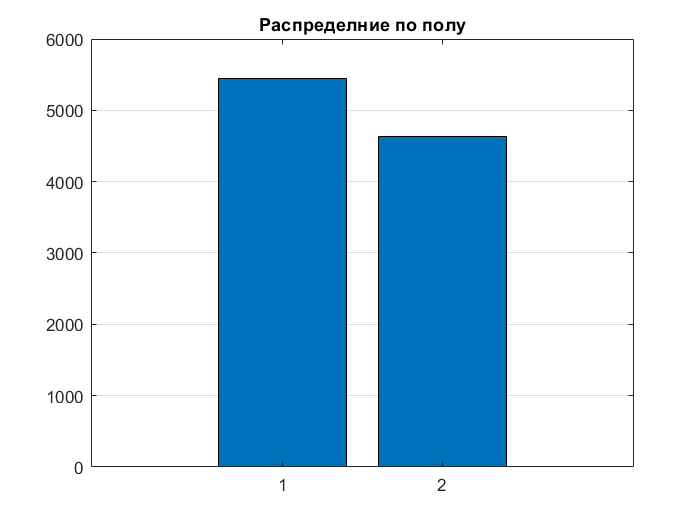

figure
bar(n)

set(gca,'XGrid','off','YGrid','on')
title('Распределние по полу')

Нажмите на построенный график. В ленточном меню сверху откроется вкладка **FIGURE**. Она содержит инструменты для быстрой настройки графика

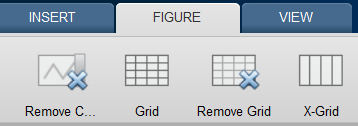

Нажмите на кнопку **Y-Grid**, чтобы активировать сетку по оси ординат.

Нажмите на нопку **Title** и добавьте графику заколовок: **Распределение по полу**.

После этих действий рядом с графиком появляется MATLAB-код, который выполняет все те, действия, что вы проделали вручную. Нажмите кнопку **Update Code** рядом с графиком, чтобы вставить этот код в скрипт. Таким образом, вам больше не понадобится настраивать график вручную, если вы его перестроите.

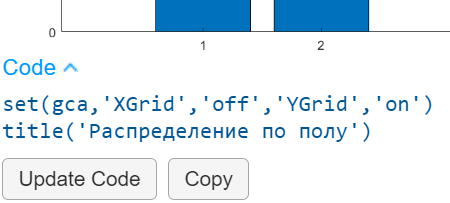

### 2. Ручная настройка в Property Editor

Если график построен в отдельной MATLAB-фигуре, его можно настроить вручную с помощью инструмента Property Editor.

Выполните код, чтобы построить график в отдельной фигуре.

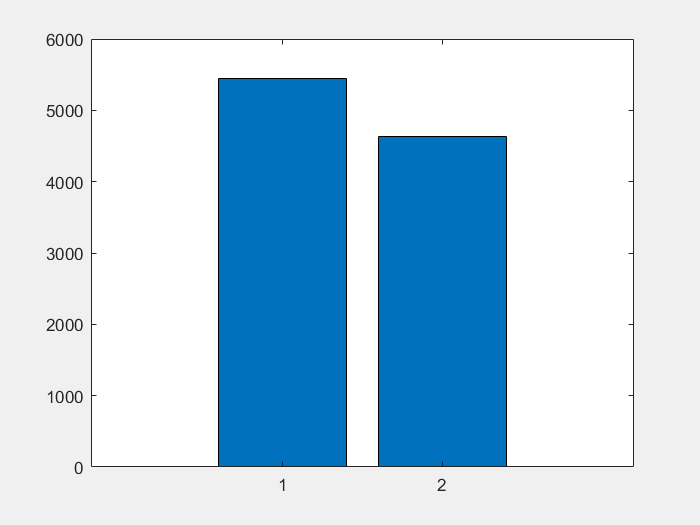

figure('Visible', 'on')
bar(n)

В меню **View** включите **Property Editor**

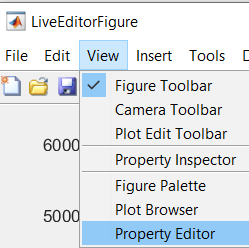

Нажмите на любой из столбиков диаграммы и в нижней части окна фигуры откроются свойства диаграммы. Задайте **ширину** столбика **1** (**Bar Witdh: 1.0**)

Нажмите на белый прямоугольник, в котором построен график, и откроются свойства осей. В левом нижнем углу включите **сетку по Y** (**Grid: Y**) и подпишите график (**Title: Распределение по полу**)

Нажмите на серое пространство вокруг осей и в открывшихся свойствах фигуры поменяйте её **цвет** на **белый** (**Figure Color: white**)

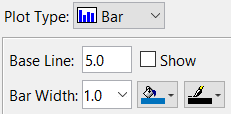 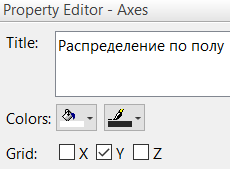 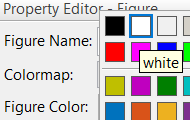

Итоговый график вы можете сохранить на диск (**File -> Save**) как MATLAB фигуру, которую можно редактировать (.fig), или как картинку (.png, .jpg, .emf, ...)

Чтобы не потерять все настройки, сделанные вручную, сгенерируйте из фигуры MATLAB-код (**File -> Generate Code...**). Этот код строит в точности такую же фигуру со всеми настройками. Скопируйте все команды, которые настраивают график, и вставьте в живой скрипт сразу после построения графика.

### 3. Ручная настройка в Property Inspector

Расширяет предыдущий способ. **Property Inspector** показывает и позволяет редактировать все свойства графических объектов. В то время, как первые 2 способа дают доступ только к некоторым свойствам.

Постройте график в отдельной фигуре.

figure('Visible', 'on')
bar(n)

На панели инструментов нажмите последнюю кнопку **Open Property Inspector**

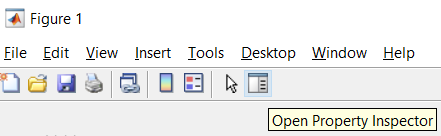

Откроется инспектор свойств. По-умолчанию в него выводятся свойства осей. Выбирая мышкой другие графические объекты (графики, фигуры, текст, ...), вы получите доступ к их свойствам. Настроим оси.

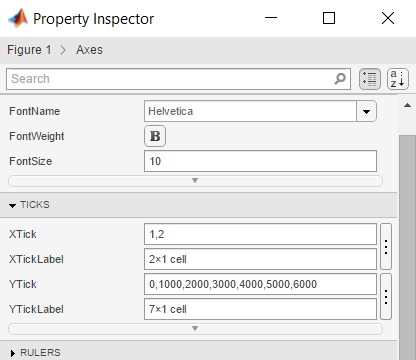

В разделе **TICKS** задайте подписи по оси абсцисс ка вектор-столбец с текстом (**XTickLabel: {'Мужчины';'Женщины'}**) (для удобства задания подписей можете нажать на кнопку с тремя точками справа от поля ввода)

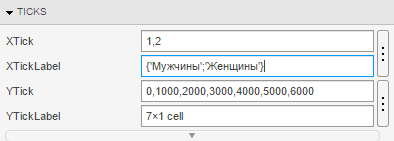

После задания свойства график автоматически изменяется.

Изучите остальные свойства осей, столбиков и фигуры и задайте их, как считаете нужным. После, как и в п.2, сгенерируйте MATLAB-код и вставьте его в живой скрипт.

### 4. Настройка с помощью функций

Построим столбчатую диаграмму, отражающую количество мужчин и женщин в выборке

figure
bar(n)

В MATLAB присутствует ряд функций для быстрой настройки построенных графиков. Они изменяют свойства построенных осей.

Например, включим сетку на графике

grid on

Подпишем график

title('Распределение по полу')

Подпишем оси ординат

ylabel('Количество людей')

Подпишем засечки на оси абсцисс

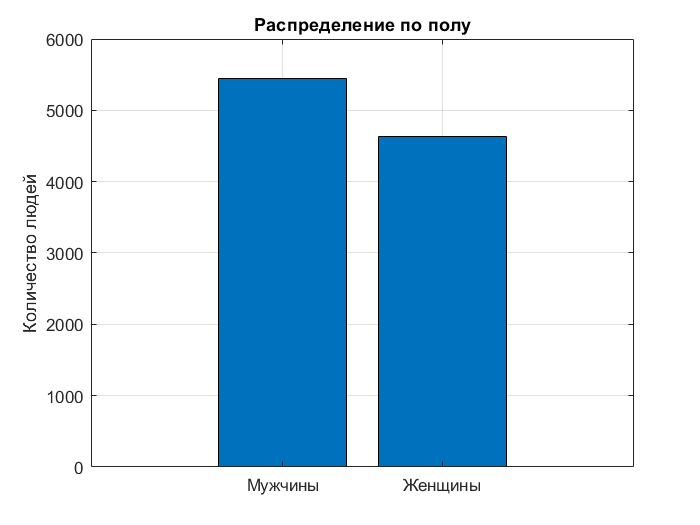

xticklabels({'Мужчины'; 'Женщины'})

Количество подобных функций ограничено лишь самыми необходимыми. Полный их список приведен в документации

### 5. Настройка через управление свойствами

MATLAB дает вам программный доступ ко всем свойствам графических объектов. Чтобы им воспользоваться, надо получить указатель на графический объект. Проще всего это сделать сразу при создании объекта.

Например, создадим новую фигуру, и запишем указатель на неё (handler) в переменную `f`

f = figure;

В фигуре `f` создадим оси с указателем `a `(оси создаются именно в фигуре `f` только потому, что команды идут последовательно). Если оси не создавать вручную, то они создаются атвоматически при построении графика

a = axes;

И в осях `a` построим график `bar`, на который будет ссылаться переменная `b `(график строится именно в осях `a` только потому, что команды идут последовательно)

b = bar(n);

Выполните в окне команд переменные `f`, `a`, `b` и убедитесь, что они действительно ссылаются на соответствующие графические объекты и открывают доступ к их свойствам.

Добавим сетку по оси ординат

a.YGrid = 'on';

Подпишем график

a.Title.String = 'Распределение по полу';
a.Title.Color = 'red';

Подпишем оси ординат

a.YLabel.String = 'Количество людей';

Подпишем засечки на оси абсцисс

a.XTickLabel = {'Мужчины'; 'Женщины'};

Увеличим толщину столбиков

b.BarWidth = 1;

Изменим цвет столбиков

b.FaceColor = 'green';

Добавим столбикам прозрачности

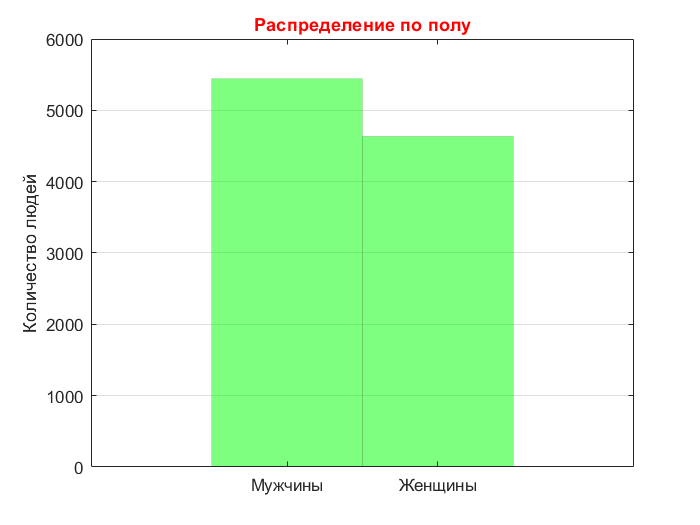

b.FaceAlpha = 0.5;
b.EdgeAlpha = 0.1;

Кстати, получить указатель на текущую фигуру можно также командой `gcf`, а на последние оси - командой `gca`

### 6. Доступ к свойствам через set/get

Функции `set`/`get `дают альтернативный доступ к свойствам объектов. Преимущество этого способа перед предыдущим, пожалуй, только в том, что он позволяет задавать сразу несколько свойств и сразу нескольким объектам.

Построим столбчатую диаграмму, отражающую количество мужчин и женщин в выборке

figure
bar(n)

Кстати, если график уже построен, а указателя на него нет, то получить указатель на текущую фигуру можно командой `gcf`, а на последние оси - командой `gca`

Настроим созданные только что оси

set(gca, 'YGrid', 'on', 'XTickLabel', {'Мужчины'; 'Женщины'})

Получим указатель на график

b = get(gca, 'Children');

Настроим график

set(b, 'BarWidth', 1, 'FaceColor', 'none', 'EdgeColor', 'red')

А вот подписать оси таким способом может быть не очень просто. Так что воспользуемся специальной функцией (комбинируем подход с п.4)

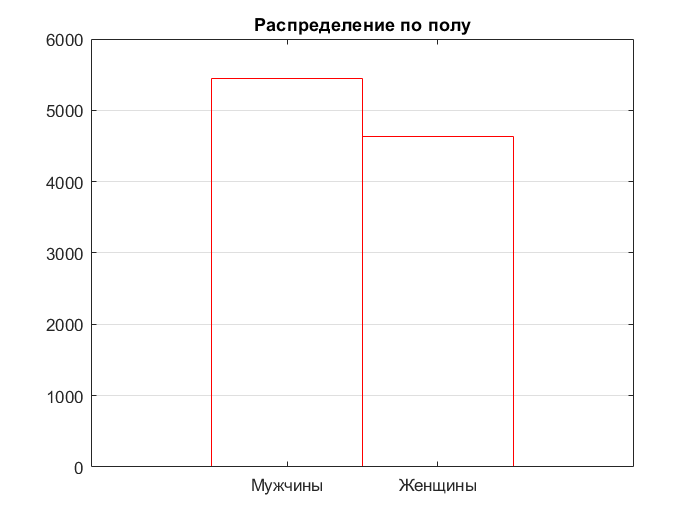

title('Распределение по полу')

### 7. Задание свойств при построении

Свойства графических объектов также можно задавать сразу при их создании. Для этого при вызове функции, которая создает объект, надо последними аргументами передать названия и значения свойств.

Создаем фигуру с **именем "Демография"**`,`** белым фоном **и свойством **Visible: on** (это откроет её в новом окне)

figure('Name', 'Демография', 'Color', 'white', 'Visible', 'on')

Создадим диаграмму с шириной столбика 1 красного цвета

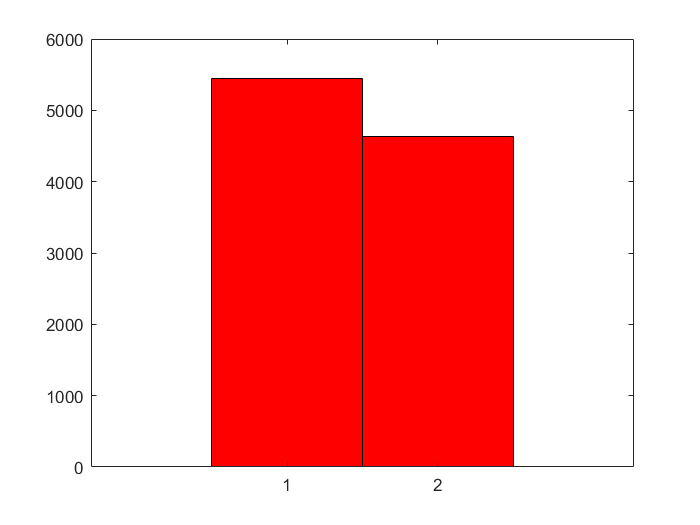

bar(n, 'BarWidth', 1, 'FaceColor', 'red')

### Какой способ выбрать?

Мы рассмотрели 7 способов настройки графиков - 3 с использованием графического интерфейса и 4 чисто программных. Среди них нет способов лучше или хуже - выбирайте то, что вам удобнее.

Если вы только начинаете работать в MATLAB и еще не освоили команды, вам подойдут 1 и 2 подходы:

- если работаете в Live Editor - п.1

- если работаете в окне команд или классических скриптах - п.2 (Property Editor)

Сразу после этого переходите к п.4 и начинайте использовать специальные функции (их немного, и их легко запомнить). Создавайте скрипты, которые строят сразу настроенные графики.

Когда наберетесь опыта, переходите к п.5 (управление свойствами) и п.7 (задание свойств при построении). Это даст вам полную свободу в работе с графикой, и вы сможете получать именно те графики, которые вам нужны.

Способ 6 (set/get) можете применять для более удобной работы в некоторых задачах.

Property Inspector (п.3) можно использовать для изучения и поиска свойств графических объектов и их изменения "на лету".

И, наконец, комбинируйте все эти способы для более удобной работы.

**Пример**

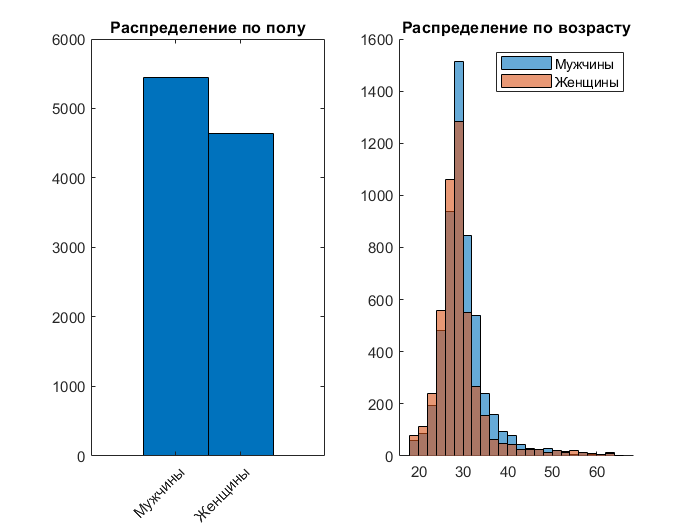

f = figure;
a1 = subplot(1, 2, 1); % создаем в фигуре оси a1
b = bar(a1, n, 'BarWidth', 1); % строим график в осях a1 с заданной шириной столбика
% Настраиваем оси a1
title(a1, 'Распределение по полу');
a1.XTickLabel = {'Мужчины'; 'Женщины'};
a1.XTickLabelRotation = 45;
a2 = subplot(1, 2, 2); % создаем в фигуре вторые оси a2
a2.NextPlot = 'add'; % готовим оси к построению нескольких графиков
h1 = histogram(a2, M);
h2 = histogram(a2, F);
set([h1 h2], 'BinWidth', 2) % настраиваем сразу 2 графика
% Настраиваем оси a2
title(a2, 'Распределение по возрасту')
legend(a2, {'Мужчины', 'Женщины'})

## Что дальше?

Ознакомьтесь с [примерами](https://www.mathworks.com/examples/matlab/category/graphics) из документации.

Изучите список графиков [MATLAB Plot Galley](https://www.mathworks.com/products/matlab/plot-gallery.html).

Начните строить свои графики.

Если столкнулись со сложностями, пользуйтесь поиском. Пример запроса в Google:* matlab how to plot thick line*